# Estimation of a Constant Using a Kalman Filter

## Introduction

- Suppose we acquire measurements of a quantity that we know to be **constant**, or at most admits of **step changes**. 

- The *observations* we have are affected by *measurement noise* (as usual, the measurement sensor introduces noise into the measurement result). 

- How can we use a Kalman **filter** as an optimal predictor of the (constant) quantity?

Voglio il filtro, quindi $x(t|t)$

## The Model

What could be the description in **state equations** of the dynamics of a **variable** that is actually **constant** (thus **NOT varying in time**)?

If we denote by $x(t)$ the state variable at the time instant $t$, representing the constant to be estimated, the dynamics of this state variable over time is:


$$\left\{
\begin{array}{rcl}
  x(t+1) &=& x(t) + v_1(t) \\
y(t) &=& x(t) + v_2(t)
\end{array} \right. \qquad \Longleftrightarrow \quad
\begin{array}{l}
v_1(\cdot) \sim \mathrm{WGN}\left(0,\,\lambda_1^2\right) \\
v_2(\cdot) \sim \mathrm{WGN} \left(0,\, \lambda_2^2\right)
\end{array}
$$


## The Code - Initialization

clear
clc
close all

## Setting the Model Features

% Model characteristics
% x(t+1) = F * x(t) + v1(t) ---> F: State transition matrix, v1 = N(0,V1) : Process noise
% y(t) = H * x(t)   + v2(t) ---> H: Output matrix          , v2 = N(0,V2) : Observation noise

StateDim = 1;                      % Number of states 
ObsDim = 1;                        % Number of observations 

DeltaT = 0.01;                     % sampling time

F = [1   ];

H = zeros(ObsDim,StateDim);        
H(:,1) = 1;                        % Matrix H 

N  = 3*12000;                       % how many datapoints?
X  = zeros(StateDim,N);            % State data buffer
y  = zeros(ObsDim,N);              % Observation data buffer

timeSteps = (0:N-1)*DeltaT;         % sampling time instants

xh_prior = zeros(StateDim,N);        % buffer for the Kalman 1-step ahead predictor 
xh_filt = zeros(StateDim,N);         %  filterbuffer for the Kalman filter as
yh = zeros(size(y));                  % output estimation buffer
e  = zeros(size(yh));                 % innovation buffer
Pmat = zeros(StateDim, StateDim, N);  % buffer for the P matrices
K0mat = zeros(StateDim, ObsDim, N);   % buffer for the Kalman filter gain
Kmat = zeros(StateDim, ObsDim, N);    % buffer for the Kalman predictor  gain

## Generation of the Process Noise

Generation of the noise affecting the state equations. In this way we can also express the uncertainty of the model (what if the constant is not really constant?).

V1=10e-2;  %zeros(1); % Process Noise Covariance Matrix % <--- What happens if we set V1 to 0?
PNoise = sqrt(V1)*randn(StateDim,N); % Process Noise

## Generation of the Measurement Noise

%% Generate Observation Noise (Noise of the output equation0
V2 = 8e-1;      % Observation Noise Covariance Matrix
Mu_ONoise = 0;  % Observation Noise mean
Std_ONoise = sqrt(V2);    % Standard deviation of the observation noise
ONoise = Std_ONoise * randn(ObsDim,N) + Mu_ONoise*ones(ObsDim,N);    % Gaussian Observation Noise


## Initialization of the Model

%% Initial values for the model
X(:,1) = [2];                   % Initial state
y(1) = H * X(:,1) + ONoise(:,1);   % Initial observation


## Generation of the Data

dd = zeros(StateDim, N);
dd(3451)=-3; % to force a "jump"  at the time instant t = 3451 * DeltaT

% Simulate states and observations
% saving results into the buffers X and y
for t = 1 : N-1
    X(:,t+1) = F * X(:,t) +dd(t);%+ PNoise(:,t); % States
    y(:,t) = H * X(:,t)   + ONoise(:,t); % Real Observations
end
 y(:,N) = H * X(:,N)   + ONoise(:,N);

### Plotting the data:

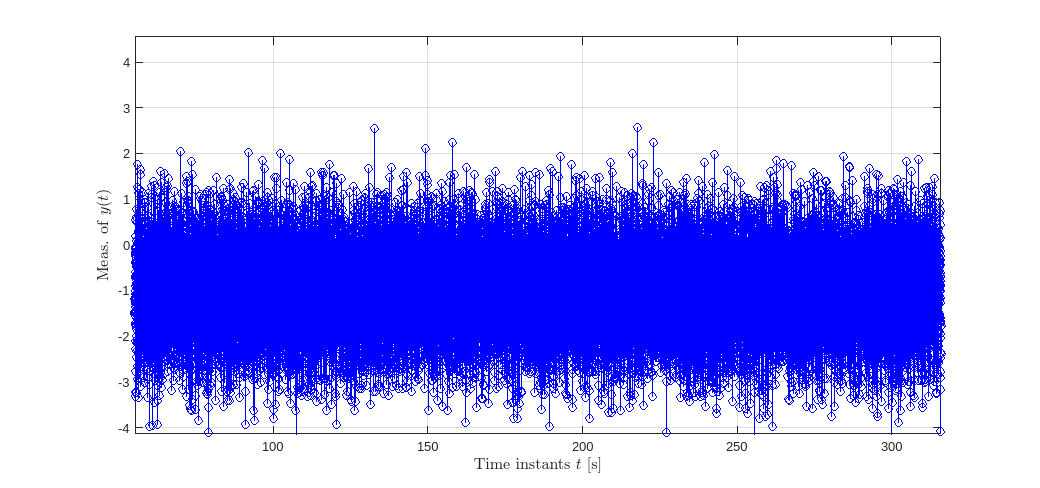

 figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);

plot(timeSteps, y,'bo-'); 
grid on; zoom on;
xlim([min(timeSteps), max(timeSteps)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
ylabel('Meas. of $y(t)$',  'Interpreter','latex','FontSize',12);

## Kalman Filtering

Note: we are evaluating both the Kalman one-step-ahead preditor and the Kalman filter

%% Kalman filtering...
% initialization
xh_prior(:,1) = X(:,1); %zeros(StateDim,1);    % Initial state
P1 = 0.1* eye(StateDim);             % Initial state covariance matrix
Pmat(:,:,1) = P1;

% KF as filter
for t = 1 : N-1  
    yh(:,t) = H * xh_prior(:,t); % a priori output estimation
    e(t) = y(:,t) - yh(:,t); % innovation 
    K0mat(:,:,t) = Pmat(:,:,t)*H'*inv(H*Pmat(:,:,t)*H'+V2); % actual Kalman gain
    Kmat(:,:,t) = F*  K0mat(:,:,t);
    xh_prior(:,t+1) = F*xh_prior(:,t)+Kmat(:,:,t)*e(:,t); % state predictor
    Pmat(:,:,t+1) = [F-F*Kmat(:,:,t)*H]*Pmat(:,:,t)*[F-F*Kmat(:,:,t)*H]'+V1+F*Kmat(:,:,t)*V2*(F*Kmat(:,:,t))';
    % updating the state error covariance matrix (DRE)
    xh_filt(:,t) = xh_prior(:,t)+K0mat(:,:,t)*e(:,t); % KF AS FILTER
end % for 
yh(:,N) = H * xh_prior(:,N); % a priori output estimation
e(N) = y(:,N) - yh(:,N); % innovation 
K0mat(:,:,N) = Pmat(:,:,N)*H'*inv(H*Pmat(:,:,N)*H'+V2); %#ok<*MINV> % actual Kalman gain
xh_filt(:,N) = xh_prior(:,N)+K0mat(:,:,N)*e(:,N); % KF AS FILTER


### Plot the Estimation Results

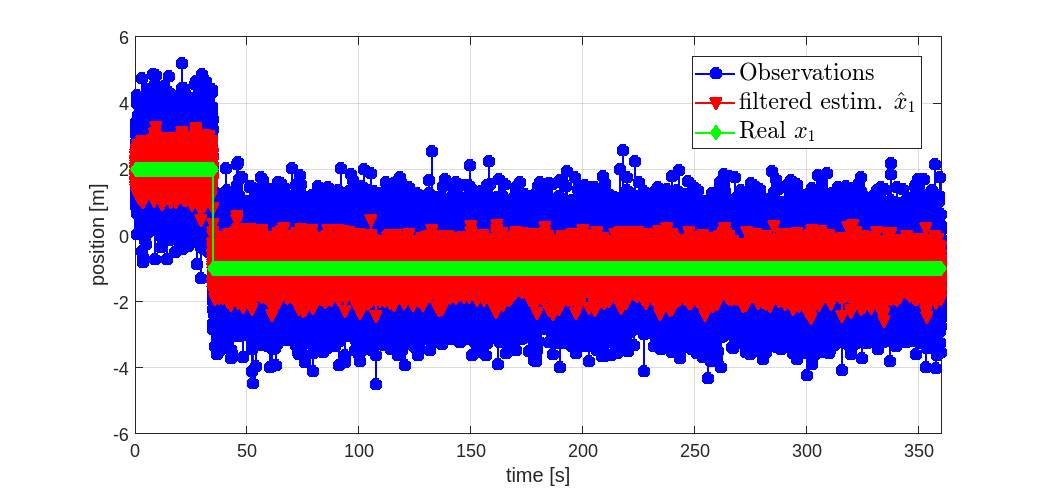

figure('Name','Observations', 'Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);
plot(timeSteps,y,'-ob', 'LineWidth',1.5,...
      'MarkerSize',8, 'MarkerFaceColor', 'b' );
xlabel('time [s]'); ylabel('position [m]');
hold on; 
grid on; zoom on;
xlim([min(timeSteps), max(timeSteps)]);
plot(timeSteps, xh_filt(1,:),'-vr',  'LineWidth',1.5,...
      'MarkerSize',8, 'MarkerFaceColor', 'r' );
plot(timeSteps, X(1,:),'-dg', 'LineWidth',1.5,...
      'MarkerSize',8, 'MarkerFaceColor', 'g');
xleg1 = legend('Observations', ...
                'filtered estim.  $\hat{x}_1$',...
                'Real $x_1$',...
        'location', 'best');
set(xleg1,'Interpreter','latex');
set(xleg1,'FontSize',18);
set(gca, 'FontSize',14);